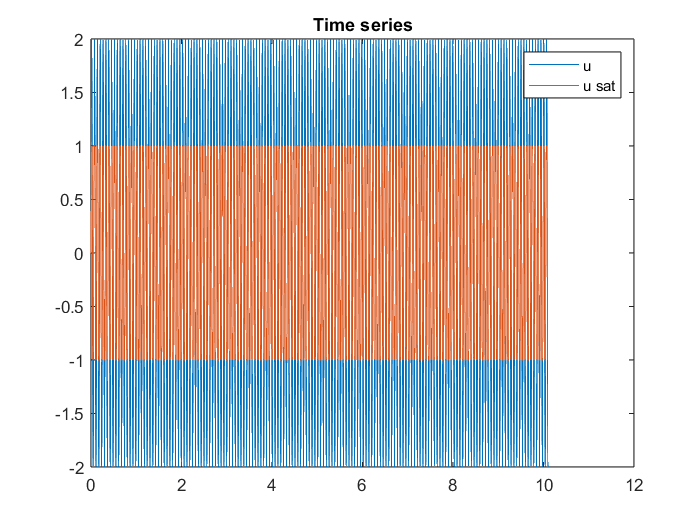

fs = 500;
t = 0:1/fs:10.1;
om = 100;
A = 2;
bounds = 1;
u = A * sin(om*t);

u_sat = sat(u,bounds);
plot(t,u)
hold on
plot(t,u_sat)
hold off
title("Time series")
legend(["u","u sat"])

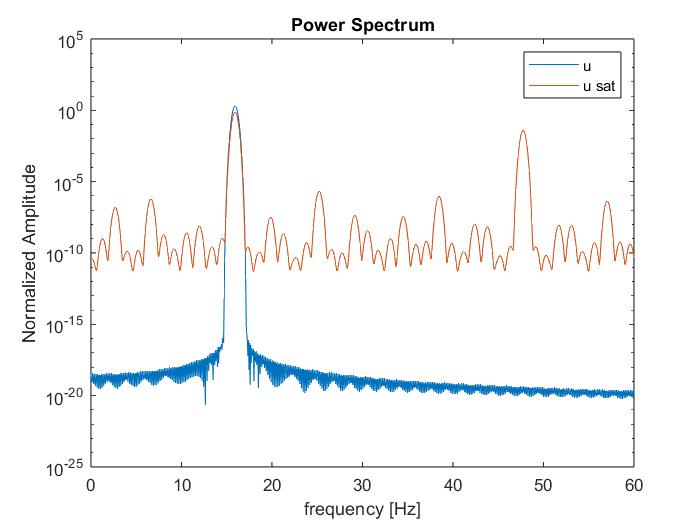

[Pu_sat, Fu_sat] = pspectrum(u_sat,fs);
[Pu, Fu] = pspectrum(u,fs);

semilogy(Fu,Pu)
title("Power Spectrum")
hold on
semilogy(Fu,Pu_sat)
hold off
ylabel("Normalized Amplitude")
xlabel("frequency [Hz]")
legend(["u","u sat"])
xlim([0 60])

We can see how a saturation creates high order armonics: the low pass filter has to placed after the saturations

% Standard low pass
lp = tf([1],[1/314 1])


lp =
 
        1
  --------------
  0.003185 s + 1
 
Continuous-time transfer function.



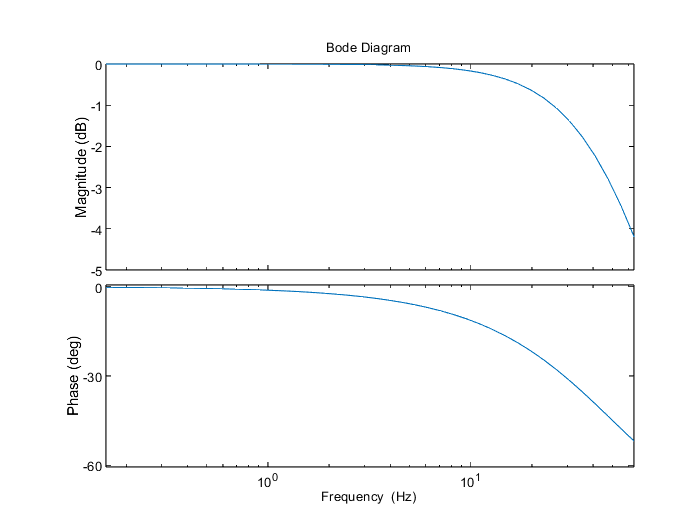

opts = bodeoptions;
opts.FreqUnits = 'Hz';
bodeplot(lp,{1,400} ,opts)

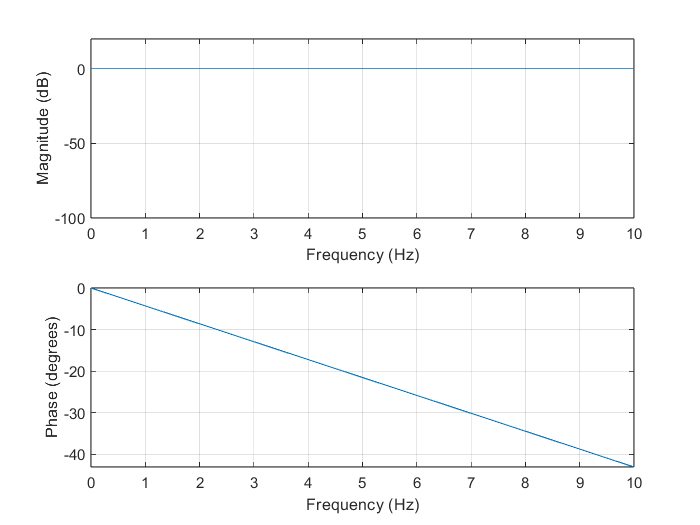


% BW Filter desgin
fc = 50;
[b,a] = butter(6,fc/(fs/2));

freqz(b,a,[0 10],fs)

subplot(2,1,1)
ylim([-100 20])

dataIn = randn(1000,1);
dataOut = filter(b,a,dataIn);

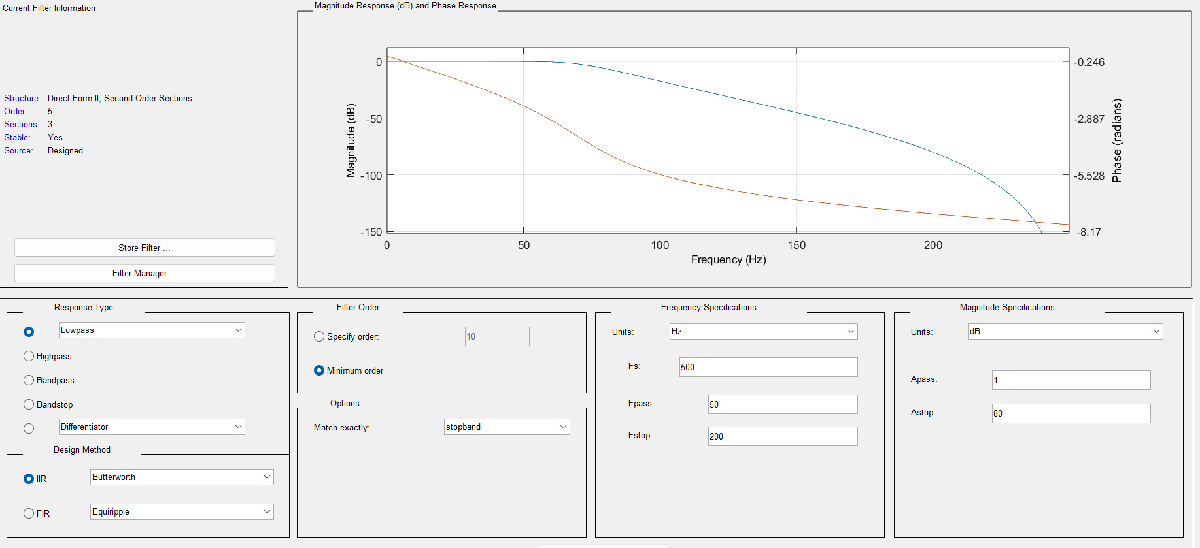

function y = sat(u,b)
y = max(-b,min(b,u));
end